# 2023-24-ex-final-q1 

# Problem 5

Consider the domain determined by the mesh `chimenea2.m` (the edge lengths are measured in $\text{mm}$). The domain is made of an elastic material with Young modulus $E = 10^{6}$ $\text{N/mm$^{2}$}$, Poisson ratio $\nu = 0.25$ and thickness $t_{h} = 0.50$ $\text{mm}$. 

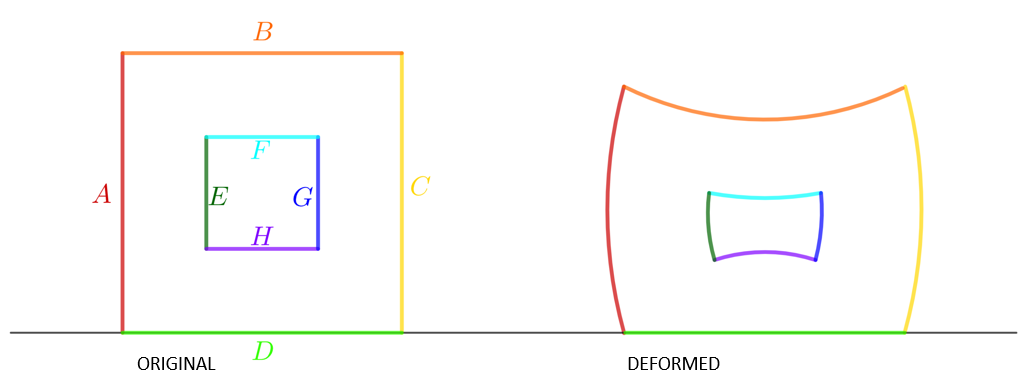

Assume that the boundaries of the mesh are defined as shown in the image and that the bottom part of the domain (corresponding to the boundary $D$) is completely fixed and that we apply a force of $-40000$ $\text{N/mm}$ in the vertical direction on the boundary $B$. Answer the following questions:

## Part (a)

(a) (2 points) The number of nodes on the boundary $B\cup E\cup F$ is:

- `76`

- Empty answer (no penalty)

- `74 `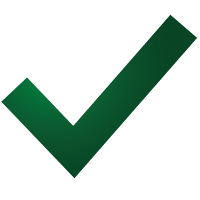

- `73`

- `75`

**Hint:** The number of nodes of boundary $B\cup E\cup F$of the mesh `chimenea0.m` is `38`.

#### Solution

clearvars
close all

Material properties and geoemetry

%Define material properties and geometry
E = 1.0e6;               %Young Modulus (in N/mm^2)
nu = 0.25;               %Poisson ratio
th = 0.50;               %Thickness (in mm)
forceLoad = [0;-4.0e4];  %Force applied on boundary B

numNodHintPartB = 111;
numNodHintPartC = 60;

%Define the plane elasticity problem: 
modelProblem=1;  %plane stress
%modelProblem=2; %plane strain 
          

Components of the stress-strain tensor

switch modelProblem %Compute the components of the stress-strain tensor
    case 1
        c11=E/(1-nu^2);
        c22=c11;
        c12=nu*c11;
        c21=c12;
        c33=E/(2*(1+nu));
        fprintf('Plane stress problem\n')
    case 2
        th=1.0;
        c11=E*(1-nu)/((1+nu)*(1-2*nu));
        c22=c11;
        c12=c11*nu/(1-nu);
        c21=c12;
        c33=E/(2*(1+nu));
        fprintf('Plane strain problem\n')
    otherwise
        error('modelProblem should be 1 (stress) or 2 (strain)');
end

Plane stress problem


Stress-strain tensor

C=[c11, c12, 0; c21, c22, 0; 0, 0, c33]; %Stress-strain tensor


**Convention:** the variables associated with the file “chimenea0.m” are designated with a trailing underscore. For example, elem_, nodes_, and indNodesBdA_ follow this naming convention.

%Convention
%When we work with the file chimenea0.m, the variables will be ended 
%by an underscore. For example elem_, nodes_, indNodesBdA_,... 

% Load the necessary data for processing
disp('Loading data for analysis...');

Loading data for analysis...


%Define material properties and geometry

E = 1.0e6;          %Young Modulus (in N/mm^2)
nu = 0.25;          %Poisson ratio
th = 0.50;          %Thickness (in mm)
Force = [0;-4e4];  %Force applied on boundary B

Computations with the mesh `chimenea0.m `(variables' names ended with an underscore) 

%eval('chimenea0');
%save 'chimenea0.mat' elem nodes -mat
%load 'chimenea0'

%Load the file with the mesh 
load 'chimenea0.mat' elem nodes
elem_ = elem; nodes_ = nodes;
whos

  Name                   Size            Bytes  Class     Attributes

  C                      3x3                72  double              
  E                      1x1                 8  double              
  Force                  2x1                16  double              
  c11                    1x1                 8  double              
  c12                    1x1                 8  double              
  c21                    1x1                 8  double              
  c22                    1x1                 8  double              
  c33                    1x1                 8  double              
  elem                 806x3             19344  double              
  elem_                806x3             19344  double              
  forceLoad              2x1                16  double              
  modelProblem           1x1                 8  double              
  nodes                459x2              7344  double              
  nodes_               459x2     

%Calculate the total number of nodes and display the information
numNod_ = size(nodes_, 1);
disp(['Total number of nodes (chimenea0.m): ', num2str(numNod_)]);

Total number of nodes (chimenea0.m): 459



% Calculate the total number of elements and display the information
numElem_ = size(elem_, 1);
disp(['Total number of elements (chimenea0.m): ', num2str(numElem_)]);

Total number of elements (chimenea0.m): 806


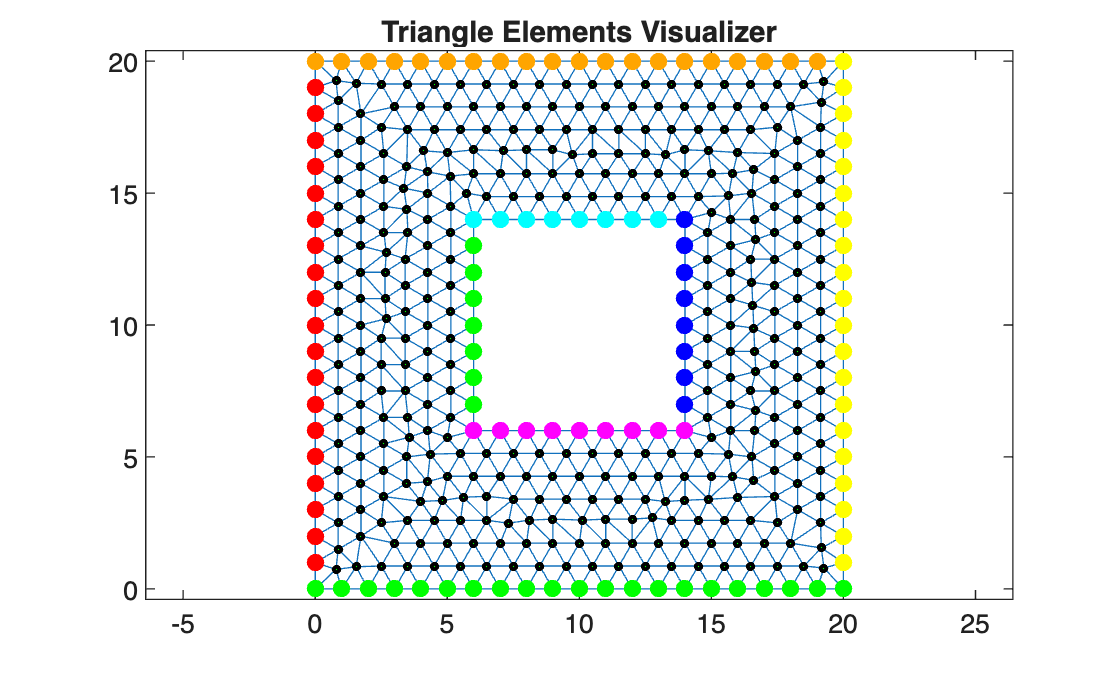

%Find out the indices of nodes at the boundaries (chimenea0)

%Nodes on the outer boundary
indNodesBdA_ = find(nodes(:,1) < 0.01);
indNodesBdB_ = find(nodes(:,2) > 19.99);
indNodesBdC_ = find(nodes(:,1) > 19.99);
indNodesBdD_ = find(nodes(:,2) < 0.01);

%Nodes on the inner boundary
indNodesBdE_ = find(nodes(:,1) < 6.01 & nodes(:,1) > 5.99 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 14.01);
indNodesBdF_ = find(nodes(:,1) > 5.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 13.99 & nodes(:,2) < 14.01);
indNodesBdG_ = find(nodes(:,1) > 13.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 14.01);
indNodesBdH_ = find(nodes(:,1) > 5.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 6.01);

%Plot all elements and nodes (chimenea0)
numbering = 0; %no labels!
figure;
plotElementsOld(nodes_, elem_, numbering)
hold on

%Plot Nodes on the inner boundary of chimenea 0
%Nodes on the outer boundary
plot(nodes(indNodesBdA_,1), nodes(indNodesBdA_,2), ...
    'o', 'markerFaceColor', 'red', 'Color', 'red');
plot(nodes(indNodesBdB_,1), nodes(indNodesBdB_,2), ...
    'o', 'markerFaceColor', '#FFA500', 'Color', '#FFA500');
plot(nodes(indNodesBdC_,1), nodes(indNodesBdC_,2), ...
    'o', 'markerFaceColor', 'yellow', 'Color', 'yellow');
plot(nodes(indNodesBdD_,1), nodes(indNodesBdD_,2), ...
    'o', 'markerFaceColor', 'green', 'Color', 'green');

%Nodes on the inner boundary
plot(nodes(indNodesBdE_,1),nodes(indNodesBdE_,2), ...
    'o','markerFaceColor','green','Color','green')
plot(nodes(indNodesBdF_,1),nodes(indNodesBdF_,2), ...
    'o','markerFaceColor','cyan','Color','cyan')
plot(nodes(indNodesBdG_,1),nodes(indNodesBdG_,2), ...
    'o','markerFaceColor','blue','Color','blue')
plot(nodes(indNodesBdH_,1),nodes(indNodesBdH_,2), ...
    'o','markerFaceColor','magenta','Color','magenta')

hold off


indNodesBdBEF_ = [indNodesBdB_; indNodesBdE_; indNodesBdF_];

indNodesBdBEF_ = unique(indNodesBdBEF_);

The same computations, but now using the file mesh `chimenea2.m'

%eval('chimenea2');
%save 'chimenea2.mat' elem nodes -mat
%load 'chimenea2'

%Load file with the mesh
load 'chimenea2.mat' elem nodes
whos

  Name                    Size            Bytes  Class     Attributes

  C                       3x3                72  double              
  E                       1x1                 8  double              
  Force                   2x1                16  double              
  c11                     1x1                 8  double              
  c12                     1x1                 8  double              
  c21                     1x1                 8  double              
  c22                     1x1                 8  double              
  c33                     1x1                 8  double              
  elem                 3144x3             75456  double              
  elem_                 806x3             19344  double              
  forceLoad               2x1                16  double              
  indNodesBdA_           21x1               168  double              
  indNodesBdBEF_         38x1               304  double              
  indNodesBdB_     


% Calculate the total number of nodes and display the information
numNod = size(nodes, 1);
disp(['Total number of nodes (chimenea2.m): ', num2str(numNod)]);

Total number of nodes (chimenea2.m): 1684



% Calculate the total number of elements and display the information
numElem = size(elem, 1);
disp(['Total number of elements (chimenea2.m): ', num2str(numElem)]);

Total number of elements (chimenea2.m): 3144


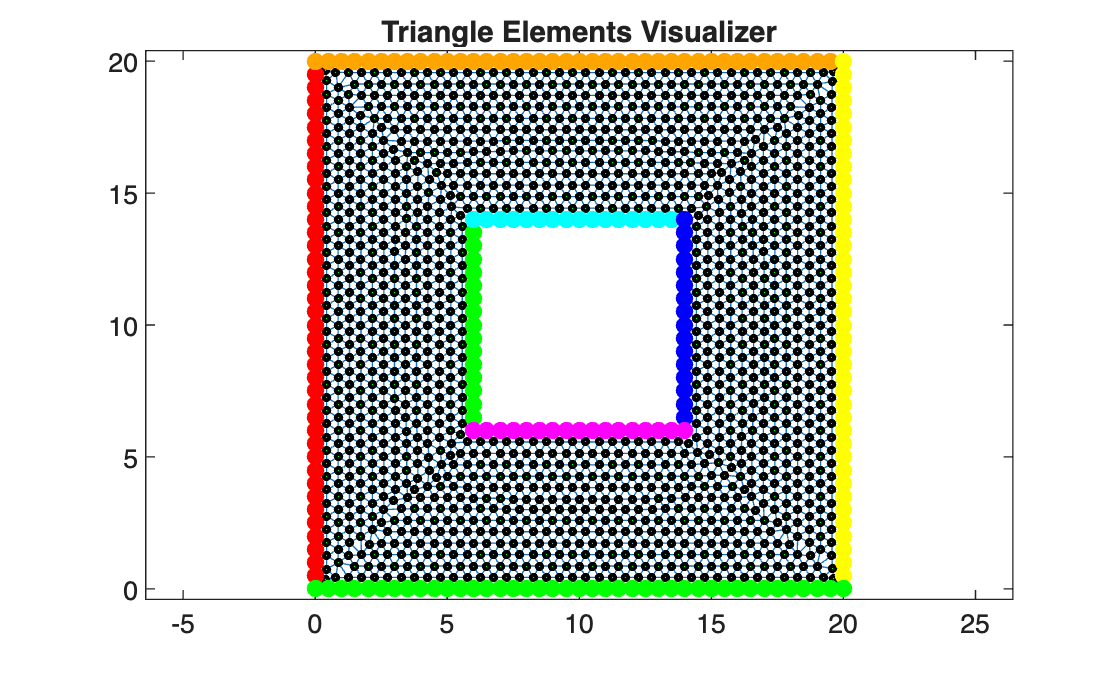


%Find out the indices of nodes at the boundaries

%Nodes on the outer boundary
indNodesBdA = find(nodes(:,1) < 0.01);
indNodesBdB = find(nodes(:,2) > 19.99);
indNodesBdC = find(nodes(:,1) > 19.99);
indNodesBdD = find(nodes(:,2) < 0.01);

%Nodes at the inner boundary
indNodesBdE = find(nodes(:,1) < 6.01 & nodes(:,1) > 5.99 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 14.01);
indNodesBdF = find(nodes(:,1) > 5.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 13.99 & nodes(:,2) < 14.01);
indNodesBdG = find(nodes(:,1) > 13.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 14.01);
indNodesBdH = find(nodes(:,1) > 5.99 & nodes(:,1) < 14.01 & ...
    nodes(:,2) > 5.99 & nodes(:,2) < 6.01);

numbering = 0; %without labels
figure;
plotElementsOld(nodes, elem, numbering)
hold on

%Nodes on the inner boundary
% Plot nodes on the outer boundary
plot(nodes(indNodesBdA,1), nodes(indNodesBdA,2), ...
    'o', 'markerFaceColor', 'red', 'Color', 'red');
plot(nodes(indNodesBdB,1), nodes(indNodesBdB,2), ...
    'o', 'markerFaceColor', '#FFA500', 'Color', '#FFA500');
plot(nodes(indNodesBdC,1), nodes(indNodesBdC,2), ...
    'o', 'markerFaceColor', 'yellow', 'Color', 'yellow');
plot(nodes(indNodesBdD,1), nodes(indNodesBdD,2), ...
    'o', 'markerFaceColor', 'green', 'Color', 'green');

plot(nodes(indNodesBdE,1),nodes(indNodesBdE,2), ...
    'o','markerFaceColor','green','Color','green')
plot(nodes(indNodesBdF,1),nodes(indNodesBdF,2), ...
    'o','markerFaceColor','cyan','Color','cyan')
plot(nodes(indNodesBdG,1),nodes(indNodesBdG,2), ...
    'o','markerFaceColor','blue','Color','blue')
plot(nodes(indNodesBdH,1),nodes(indNodesBdH,2), ...
    'o','markerFaceColor','magenta','Color','magenta')

hold off

indNodesBdBEF = [indNodesBdB; indNodesBdE; indNodesBdF];
indNodesBdBEF = unique(indNodesBdBEF);
fprintf(['(a) The number of nodes on the boundary B-E-F is: %d\n', ...
         '    Hint: The number of nodes of nodes on the boundary\n', ...
         '          B-E-F of the mesh chimenea0.m is: %d\n'], ...
         size(indNodesBdBEF,1), size(indNodesBdBEF_,1))

(a) The number of nodes on the boundary B-E-F is: 74
    Hint: The number of nodes of nodes on the boundary
          B-E-F of the mesh chimenea0.m is: 38


## Part (b)

(b) (2 points) What is the mean horizontal displacement (in $\text{mm}$) of the nodes on the boundary $C$?

- `3.5079e-01 `

- Empty answer (no penalty)

- `3.5472e-01`

- `3.3866e-01`

- `3.4554e-01`

**Hint:** The horizontal displacement (in $\text{mm}$) of the node $111$, using the same parameter and the mesh `chimenea0.m `is `6.7330e-01` $\text{mm}$. 

#### Solution

First we make the computations with mesh in file `chimenea0.m`

%First, we make the computations with the mesh in file chimenea0.m

%dimension
ndim = size(nodes_,2);

K=zeros(ndim*numNod_);
F=zeros(ndim*numNod_,1);
Q=zeros(ndim*numNod_,1);

for e=1:numElem_
    Ke=planeElastTriangStiffMatrix(nodes_,elem_,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[ndim*elem_(e,1)-1; ndim*elem_(e,1); ...
         ndim*elem_(e,2)-1; ndim*elem_(e,2); ...
         ndim*elem_(e,3)-1; ndim*elem_(e,3)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end
%Boundary conditions
fixedNod = indNodesBdD_;
fixedNod=[ndim*fixedNod-1;ndim*fixedNod];
freeNod=setdiff(1:ndim*numNod_,fixedNod);
%Natural BC: constant traction on the right boundary
nodLoads=indNodesBdB_'; %nodes where the load is applied (transposed)
Q=applyLoadsTriang(nodes_,elem_,nodLoads,Q,forceLoad);
%Essential BC: left boundary fixed
u=zeros(ndim*numNod_,1);
u(fixedNod)=0.0;

%Reduced System
%Fm=F(freeNod)-K(freeNod,fixedNod)*u_(fixedNod); %Note: here u(fixedNod)=0,
                                                 %so this is not necessary
                                                 %in this case
%Fm=Fm+Q(freeNod);
Qm=Q(freeNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Qm;
u(freeNod)=um;

displ_ = [u(1:2:end), u(2:2:end)];

Post process: plot the mesh and the displacements of the nodes (`chimenea0.m)`

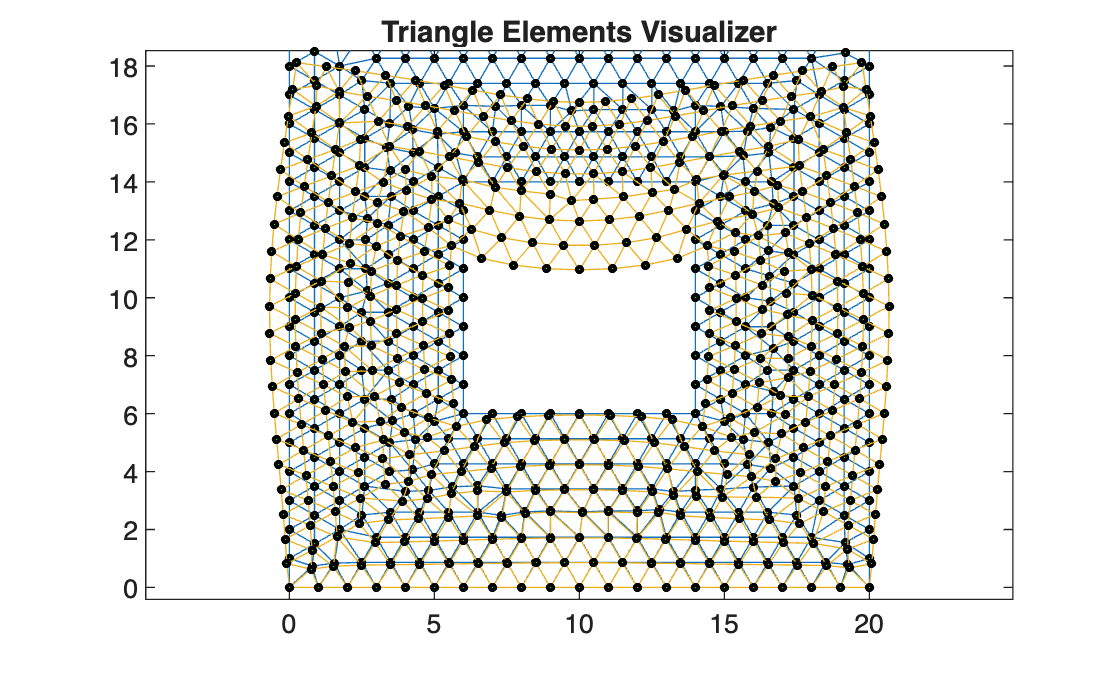

%Post process: plot the mesh and the displacements of the nodes
%(chimenea0.m)
figure;
esc = 1;
plotPlaneNodElemDespl(nodes_, elem_, u, esc)

The same computations for the mesh in `chimenea2.m`

clear K F Q Km Qm u um fixedNod freeNod

K=zeros(ndim*numNod);
F=zeros(ndim*numNod,1);
Q=zeros(ndim*numNod,1);

for e=1:numElem
    Ke=planeElastTriangStiffMatrix(nodes,elem,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[ndim*elem(e,1)-1; ndim*elem(e,1); ...
         ndim*elem(e,2)-1; ndim*elem(e,2); ...
         ndim*elem(e,3)-1; ndim*elem(e,3)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end
%Boundary conditions
fixedNod = indNodesBdD;
fixedNod=[ndim*fixedNod-1;ndim*fixedNod];
freeNod=setdiff(1:ndim*numNod,fixedNod);

%Natural BC: constant traction on the right boundary
nodLoads=indNodesBdB'; %nodes where the load is applied (transposed)
Q=applyLoadsTriang(nodes,elem,nodLoads,Q,forceLoad);
%Essential BC: left boundary fixed
u=zeros(ndim*numNod,1);
u(fixedNod)=0.0;

%Reduced System
%Fm=F(freeNod)-K(freeNod,fixedNod)*u_(fixedNod); %Note: here u(fixedNod)=0,
                                                 %so this is not necessary
                                                 %in this case
%Fm=Fm+Q(freeNod);
Qm=Q(freeNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Qm;
u(freeNod)=um;

displ = [u(1:2:end), u(2:2:end)];

Post process: plot the mesh and the displacements of the nodes (`chimenea2.m)`

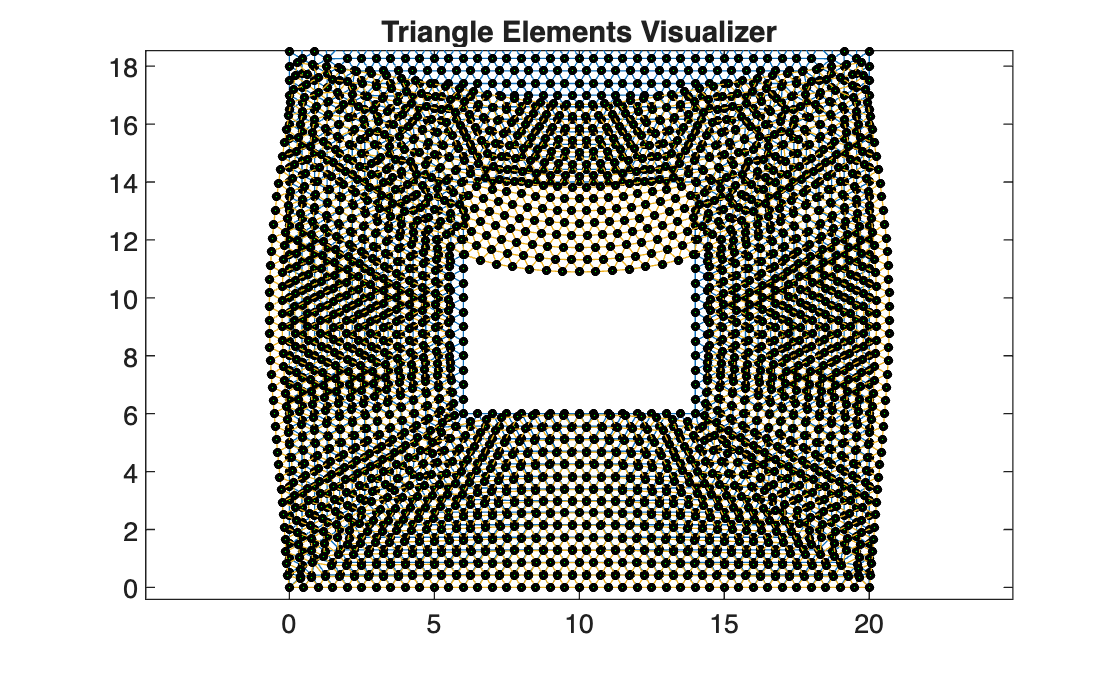

%Post process: plot the mesh and the displacements of the nodes
%(chimenea2.m)
figure;
esc = 1;
plotPlaneNodElemDespl(nodes, elem, u, esc)      

fprintf(['(b) The mean horizontal displacement of nodes ',...
         'on boundary C is: %.4e mm\n', ...
         '    Hint: The horizontal displacement of node %d ',...
         '(chimenea0.m) is: %.4e mm\n'],...
         sum(displ(indNodesBdC,1))/size(indNodesBdC,1),...     
         numNodHintPartB, displ_(numNodHintPartB,1))

(b) The mean horizontal displacement of nodes on boundary C is: 3.5079e-01 mm
    Hint: The horizontal displacement of node 111 (chimenea0.m) is: 6.7330e-01 mm


## Part (c)

(c) (3 points) What is the maximum displacement (in mm and modulus) of all the nodes? 

- `3.3689e+00`

- Empty answer (no penalty)

- `3.2338e+00`

- `3.2717e+00`

- `3.3244e+00 `

**Hint:** The displacement in modulus of the node $60$, using the same parameters and the mesh `chimenea0.m `is `3.0387e+00` $\text{mm}$.

#### Solution

normDispl = sqrt(displ(:,1).^2 + displ(:,2).^2);
normDispl_ = sqrt(displ_(:,1).^2 + displ_(:,2).^2);
fprintf(['(c) Max displacement in modulus of all nodes: %.4e\n', ...
    '    Hint: Displacement of node %d using the mesh chimenea0.m: %.4e\n'], ...
    max(normDispl), numNodHintPartC, normDispl_(numNodHintPartC))

(c) Max displacement in modulus of all nodes: 3.3244e+00
    Hint: Displacement of node 60 using the mesh chimenea0.m: 3.0387e+00


## Part (d)

(d) (3 points) What is the final area defined by the mesh elements? (This is the sum of the areas of all their elements after applying the force.)

- `3.2310e+02`

- `3.1368e+02 `

- `3.1917e+02`

- `3.0974e+02`

- Empty answer (no penalty)

**Hint:** The area before applying the force is `3.3600+e02` $\text{mm$^{2}$}$.

#### Solution

areaBeforeFL = 0.0; %Area before force load
areaAfterFL = 0.0;  %Area after force load

for e = 1:numElem
    %Position of vertexs before FL
    vertexsBeforeFL = nodes(elem(e,:),:); 
    areaBeforeFL = areaBeforeFL + 0.5 * det([ones(3,1), vertexsBeforeFL]);

    %Position of vertexs after FL   
    vertexsAfterFL = vertexsBeforeFL + displ(elem(e,:),:);
    areaAfterFL = areaAfterFL + 0.5 * det([ones(3,1), vertexsAfterFL]);     
end

fprintf(['(d) Final area defined by the mesh elements: %.4e mm%s\n', ...
         '    Hint: The area before applying the force is: %.4e mm%s\n'],...
    areaAfterFL,char(178),areaBeforeFL,char(178))

(d) Final area defined by the mesh elements: 3.1368e+02 mm²
    Hint: The area before applying the force is: 3.3600e+02 mm²
